## Setting Up

clear all
close all
clc
currentFolder = '/Users/alysolberg/Dropbox (HMS)/hyperData';
saveFolder = '/Users/alysolberg/Library/Mobile Documents/com~apple~CloudDocs/MATLAB/livelovehochbaum';
cd(currentFolder);
load CompiledPhysio_final.mat
load deltafood.mat

## Reconfiguring Tables

1.Temp reconfiguring

ID=tempMasterData.Properties.RowNames;
IDa = cell2table(ID);
IDa.Properties.RowNames = ID;
tempmasterII=[IDa tempMasterData];
tempmasterII.Properties.VariableNames{'ID'}='Master_ID';
tempmasterII.Properties.VariableNames = {'Master_ID' 'OriginalID' '-3' '-2' '-1' '0' '1' '2' '3' '4' '5' '6' '7' '8'};
dataprestack=join(tempmasterII,masterID);
dataprestack = removevars(dataprestack,{'OriginalID' 'Spreadsheet' 'ImportantNotes' 'Var14' 'Var15' 'Var16' 'Var17' 'Var18' 'Var19' 'Var20'});

2.Weight

weightmasterII=[IDa weightMasterData];
weightmasterII.Properties.VariableNames = {'Master_ID' 'OriginalID' '-3' '-2' '-1' '0' '1' '2' '3' '4' '5' '6' '7' '8'};

3.Food

foodmasterII=[IDa deltaFoodData];
foodmasterII.Properties.VariableNames = {'Master_ID' '-3' '-2' '-1' '0' '1' '2' '3' '4' '5' '6' '7' '8'};

## Stacking Individual Tables

prelimstack=stack(dataprestack,{'-3' '-2' '-1' '0' '1' '2' '3' '4' '5' '6' '7' '8'});
weightstack=stack(weightmasterII,{'-3' '-2' '-1' '0' '1' '2' '3' '4' '5' '6' '7' '8'});
foodstack=stack(foodmasterII,{'-3' '-2' '-1' '0' '1' '2' '3' '4' '5' '6' '7' '8'});

## Renaming Columns to Join Stacks

prelimstack.Properties.VariableNames{'-3_-2_-1_0_1_2_3_4_5_6_7_8'}='Temp';
prelimstack.Properties.VariableNames{'-3_-2_-1_0_1_2_3_4_5_6_7_8_Indicator'}='Day';
weightstack.Properties.VariableNames{'-3_-2_-1_0_1_2_3_4_5_6_7_8'}='Weight';
foodstack.Properties.VariableNames{'-3_-2_-1_0_1_2_3_4_5_6_7_8'}='Food';

## Reconfiguring Stacks to Join

weightstack.("-3_-2_-1_0_1_2_3_4_5_6_7_8_Indicator")=[];
weightstack.OriginalID=[];
foodstack.("-3_-2_-1_0_1_2_3_4_5_6_7_8_Indicator")=[];
weightstack.Master_ID=[];
foodstack.Master_ID=[];

## Joining Stacks

alldataprelim = [prelimstack,foodstack];
alldata = [alldataprelim,weightstack];

## Reconfiguring Deltatemp Table and Adding Master ID Info

deltatemp.Properties.RowNames=ID;
deltatempII=[masterID deltatemp];
deltatempII = removevars(deltatempII,{'Original_ID' 'Master_ID' 'Spreadsheet' 'Var14' 'Var15' 'Var16' 'Var17' 'Var18' 'Var19' 'Var20'});

## Making Deltatemp Stack

deltatempstack=stack(deltatempII,{'1' '2' '3' '4' '5' '6' '7' '8'});
deltatempstack.Properties.VariableNames{"1_2_3_4_5_6_7_8_Indicator"}='Day';
deltatempstack.Properties.VariableNames{"1_2_3_4_5_6_7_8"}='tempchange';

## Temp Boxplot

-Days limited to Habituation Day 1 through Treatment Day 3 (-1 to 3)

-Raw data

-Set color scheme to Brewer 2

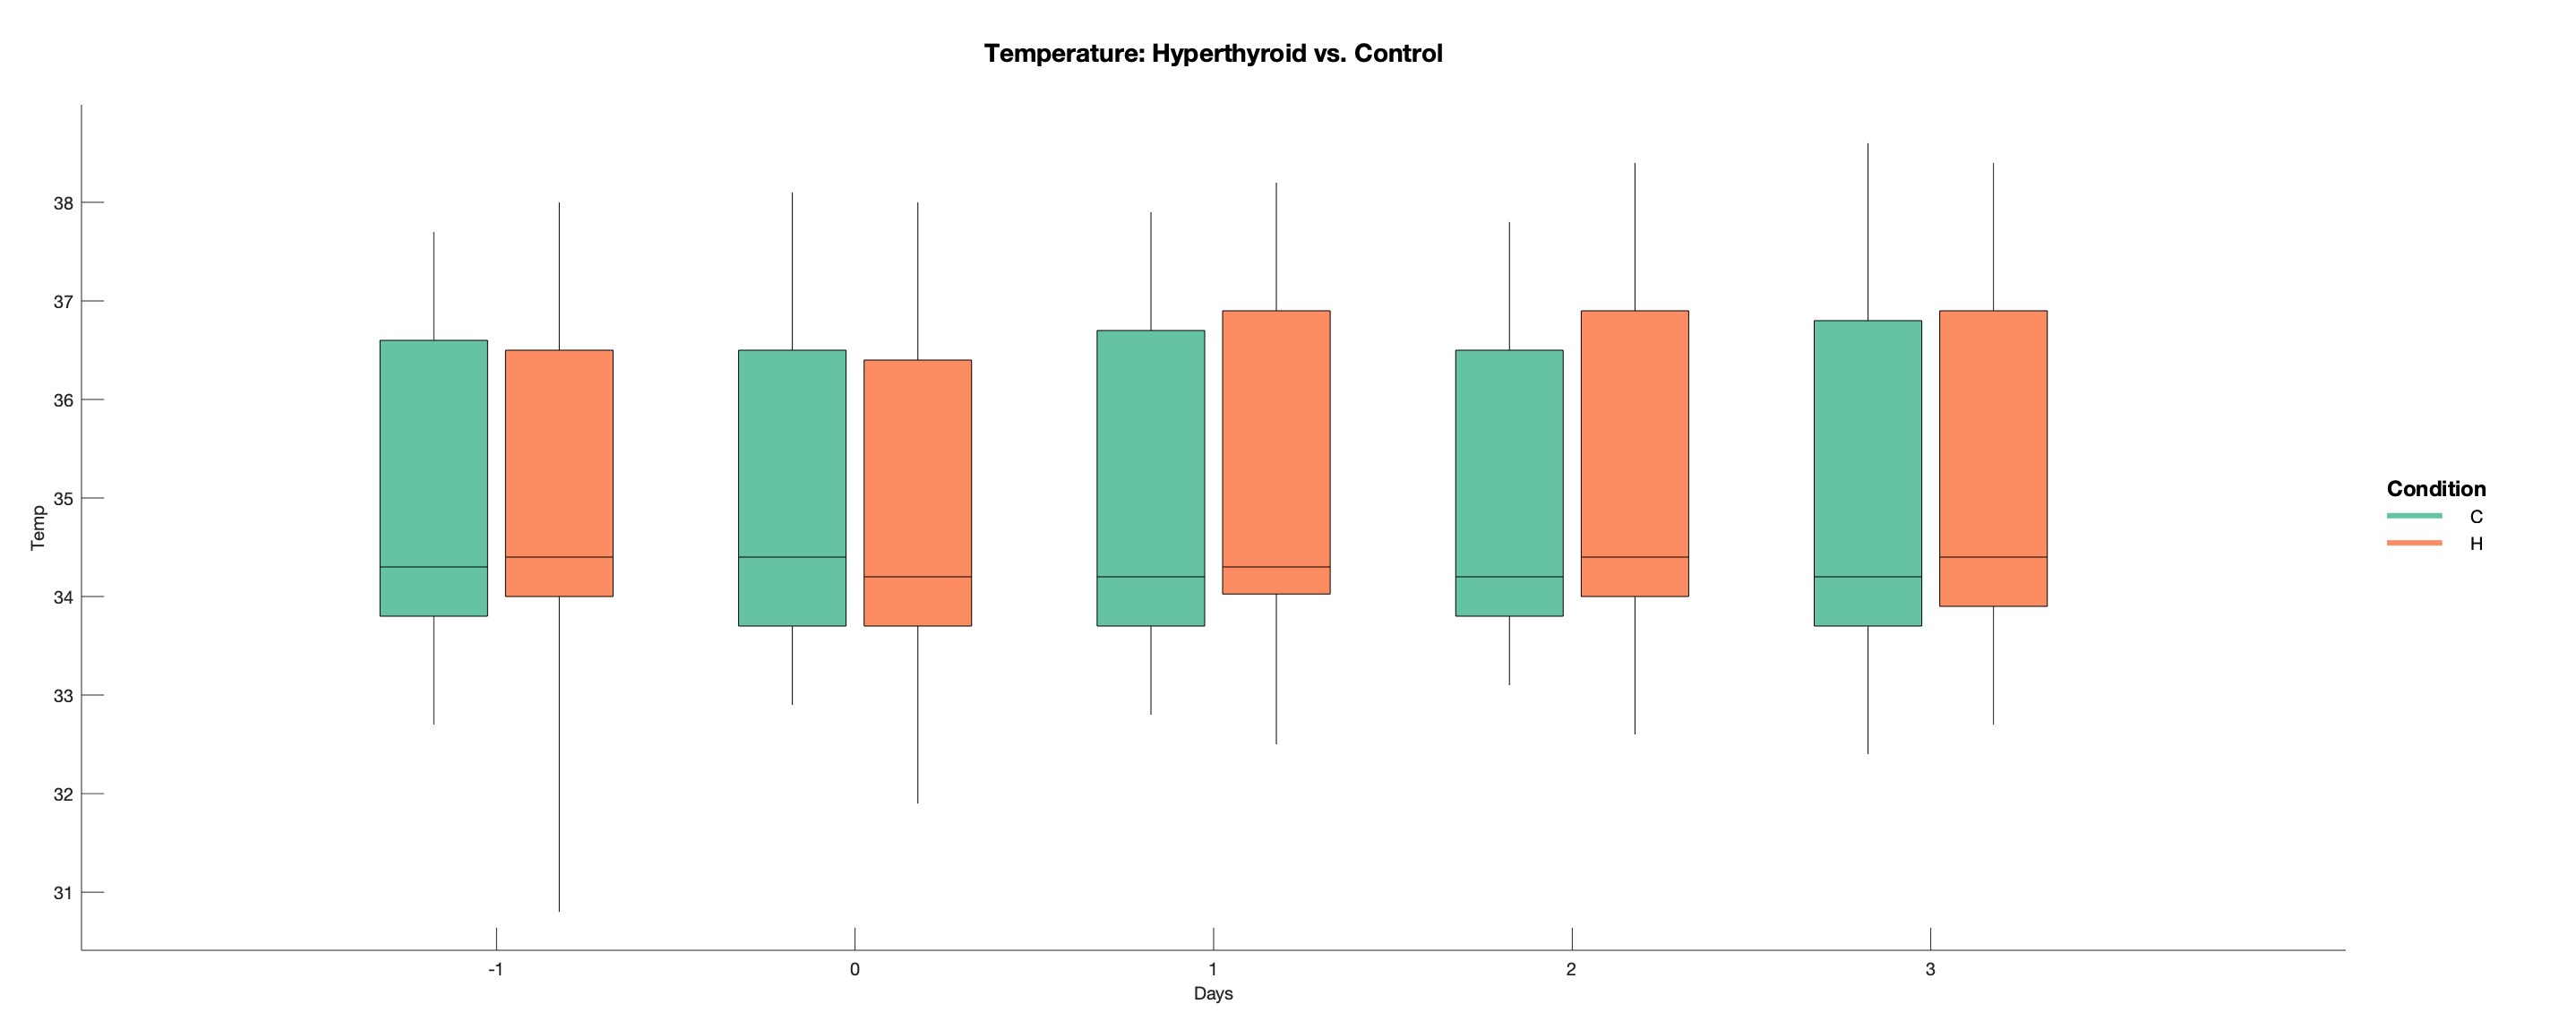

ans =   gramm with properties:

     legend_axe_handle: [1×1 Axes]
      title_axe_handle: [1×1 Axes]
    facet_axes_handles: [1×1 Axes]
               results: [1×1 struct]


a=gramm('x',alldata.Day,'y',alldata.Temp,'color',alldata.Condition_H_C_,'subset',alldata.Day~="-2" & alldata.Day~="-3" & alldata.Day~="5"& alldata.Day~="6"& alldata.Day~="7"& alldata.Day~="8" & alldata.Day~="4");
a.stat_boxplot();
a.set_names('x','Days','y','Temp','color','Condition');
a.set_title('Temperature: Hyperthyroid vs. Control');
a.set_color_options('map','brewer2');
figure('Position',[100 100 2000 800]);
a.draw()

## Temp Jittered Scatter Plot

-Days limited to Habituation Day 1 through Treatment Day 3 (-1 to 3)

-Raw data

-Set color scheme to Brewer 2

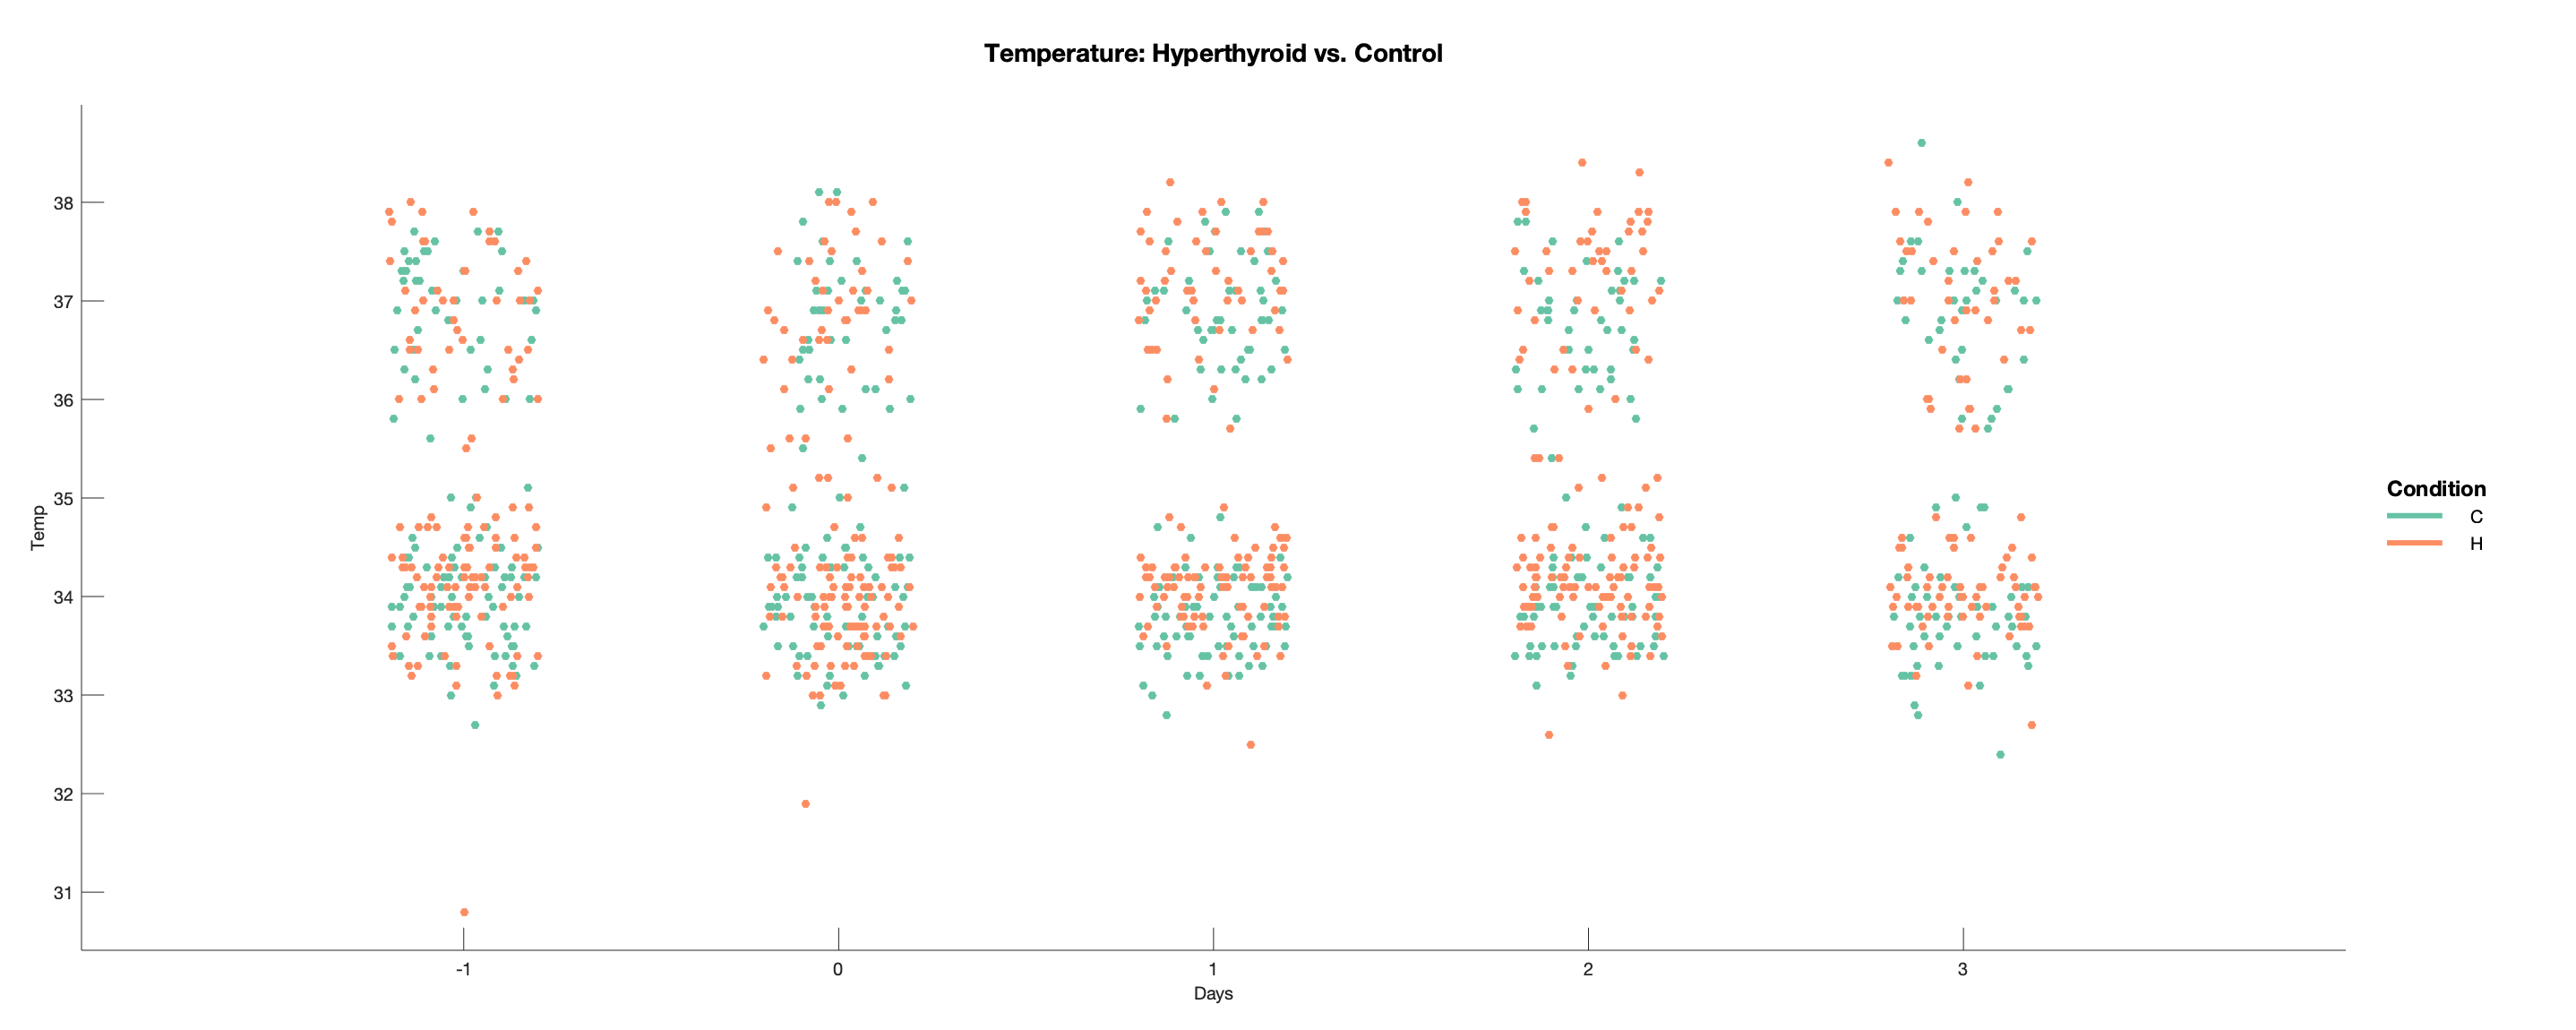

ans =   gramm with properties:

     legend_axe_handle: [1×1 Axes]
      title_axe_handle: [1×1 Axes]
    facet_axes_handles: [1×1 Axes]
               results: [1×1 struct]


a=gramm('x',alldata.Day,'y',alldata.Temp,'color',alldata.Condition_H_C_,'subset',alldata.Day~="-2" & alldata.Day~="-3" & alldata.Day~="5"& alldata.Day~="6"& alldata.Day~="7"& alldata.Day~="8" & alldata.Day~="4");
a.geom_jitter('width',0.4,'height',0);
a.set_names('x','Days','y','Temp','color','Condition');
a.set_title('Temperature: Hyperthyroid vs. Control');
a.set_color_options('map','brewer2');
figure('Position',[100 100 2000 800]);
a.draw()

## Temp Normalized Violin Plot

-Days limited to Habituation Day 1 through Treatment Day 3 (-1 to 3)

-Raw data

-Set color scheme to Brewer 2

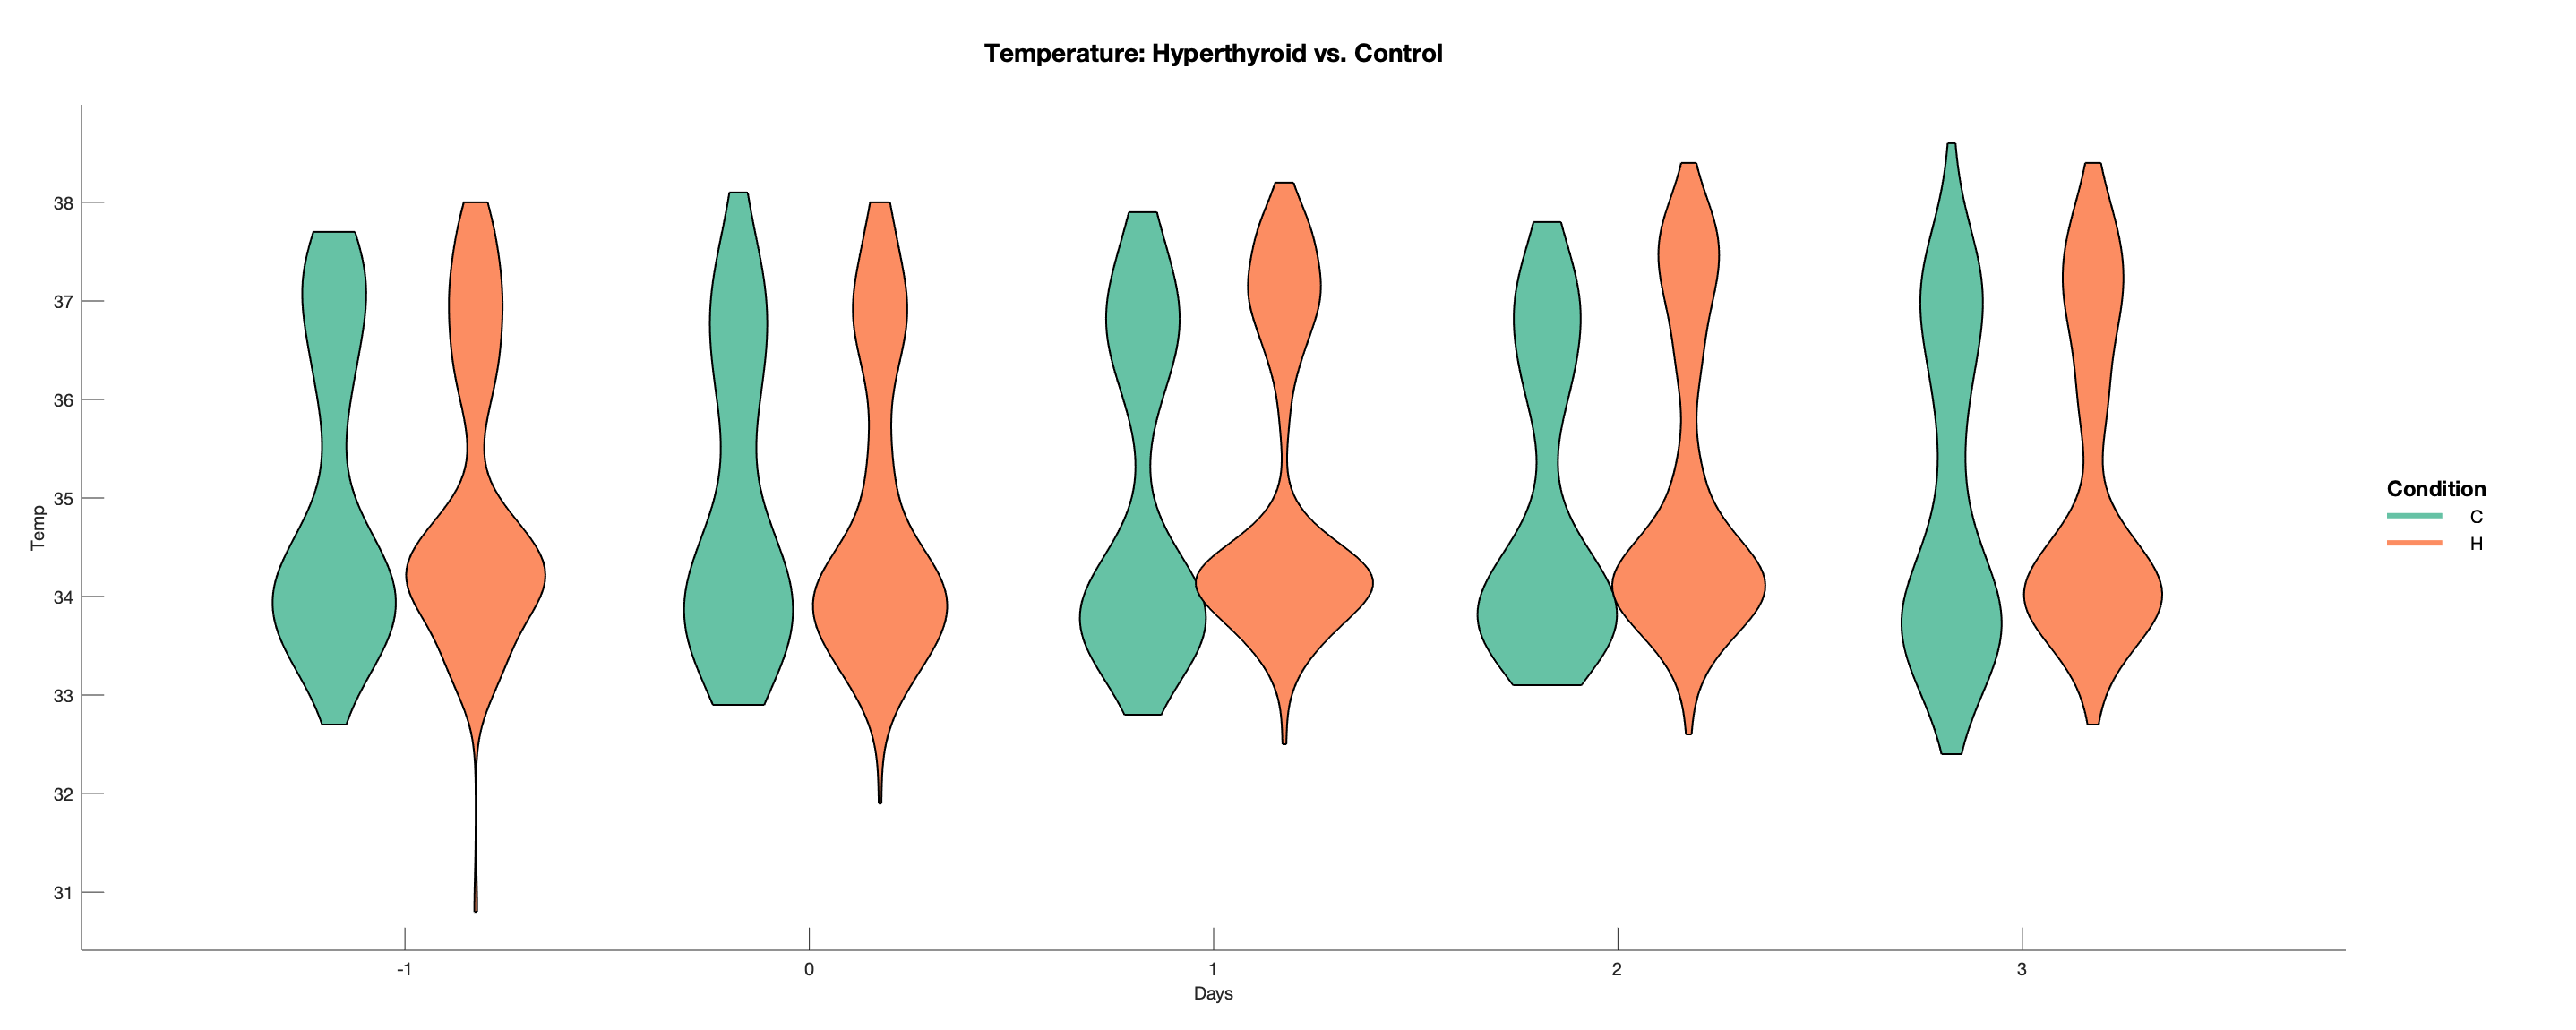

ans =   gramm with properties:

     legend_axe_handle: [1×1 Axes]
      title_axe_handle: [1×1 Axes]
    facet_axes_handles: [1×1 Axes]
               results: [1×1 struct]


a=gramm('x',alldata.Day,'y',alldata.Temp,'color',alldata.Condition_H_C_,'subset',alldata.Day~="-2" & alldata.Day~="-3" & alldata.Day~="5"& alldata.Day~="6"& alldata.Day~="7"& alldata.Day~="8" & alldata.Day~="4");
a.stat_violin('normalization','area');
a.set_names('x','Days','y','Temp','color','Condition');
a.set_title('Temperature: Hyperthyroid vs. Control');
a.set_color_options('map','brewer2');
figure('Position',[100 100 2000 800]);
a.draw()

## Temp c

-Days limited to Habituation Day 1 through Treatment Day 3 (-1 to 3)

-Raw data

-Set color scheme to Brewer Dark

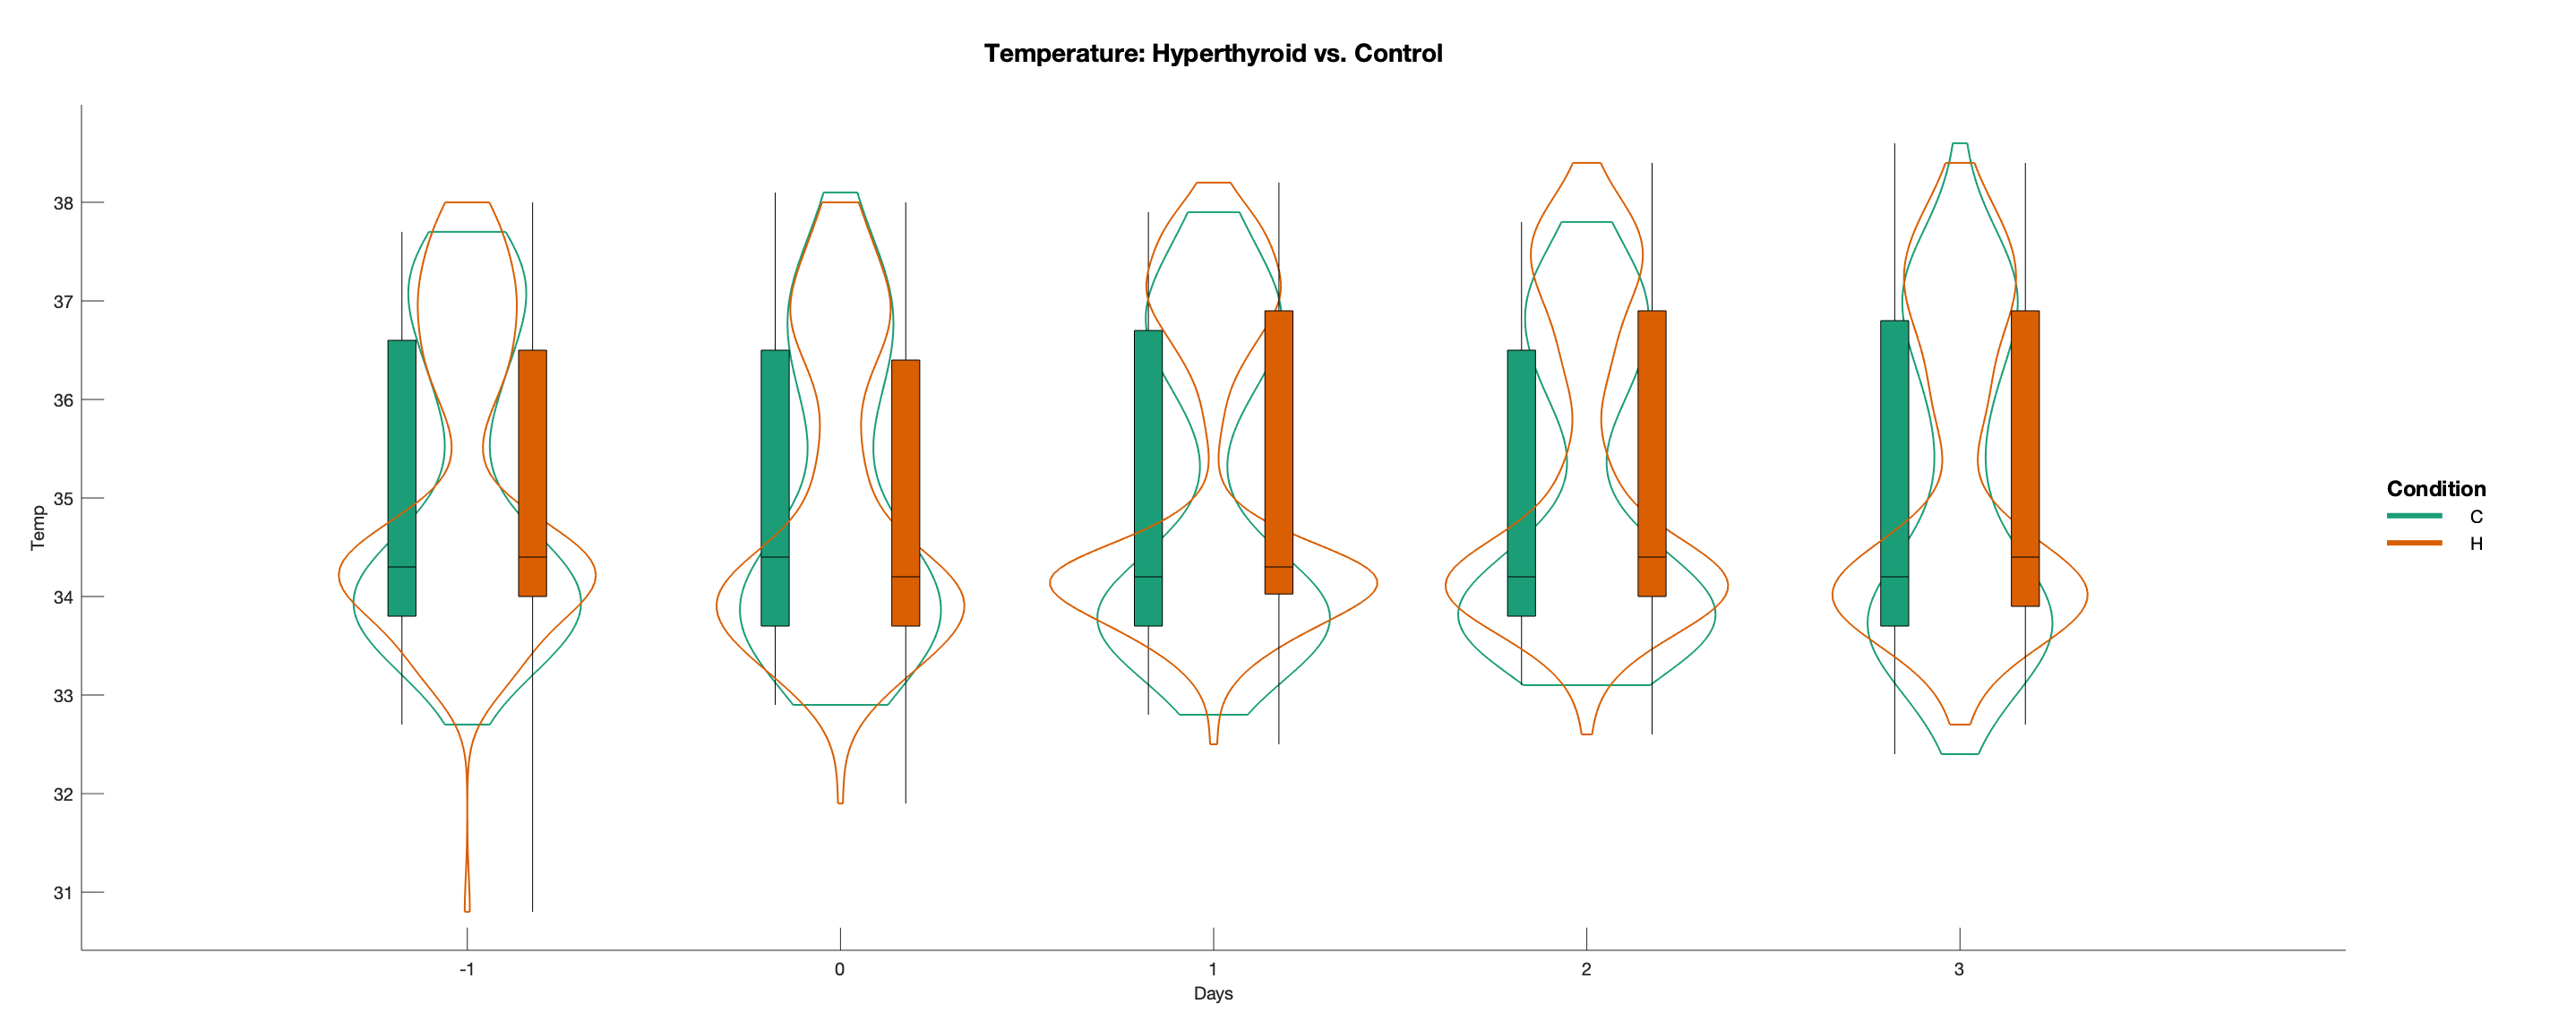

ans =   gramm with properties:

     legend_axe_handle: [1×1 Axes]
      title_axe_handle: [1×1 Axes]
    facet_axes_handles: [1×1 Axes]
               results: [1×1 struct]


a=gramm('x',alldata.Day,'y',alldata.Temp,'color',alldata.Condition_H_C_,'subset',alldata.Day~="-2" & alldata.Day~="-3" & alldata.Day~="5"& alldata.Day~="6"& alldata.Day~="7"& alldata.Day~="8" & alldata.Day~="4");
a.stat_violin('normalization','area','dodge',0,'fill','edge');
a.stat_boxplot('width',0.15);
a.set_names('x','Days','y','Temp','color','Condition');
a.set_title('Temperature: Hyperthyroid vs. Control');
a.set_color_options('map','brewer_dark');
figure('Position',[100 100 2000 800]);
a.draw()

## Delta Temp Box Plot

-Days limited to Day 1 through Day 3 of treatment

-Delta temp data 

-Set color scheme to Brewer Dark

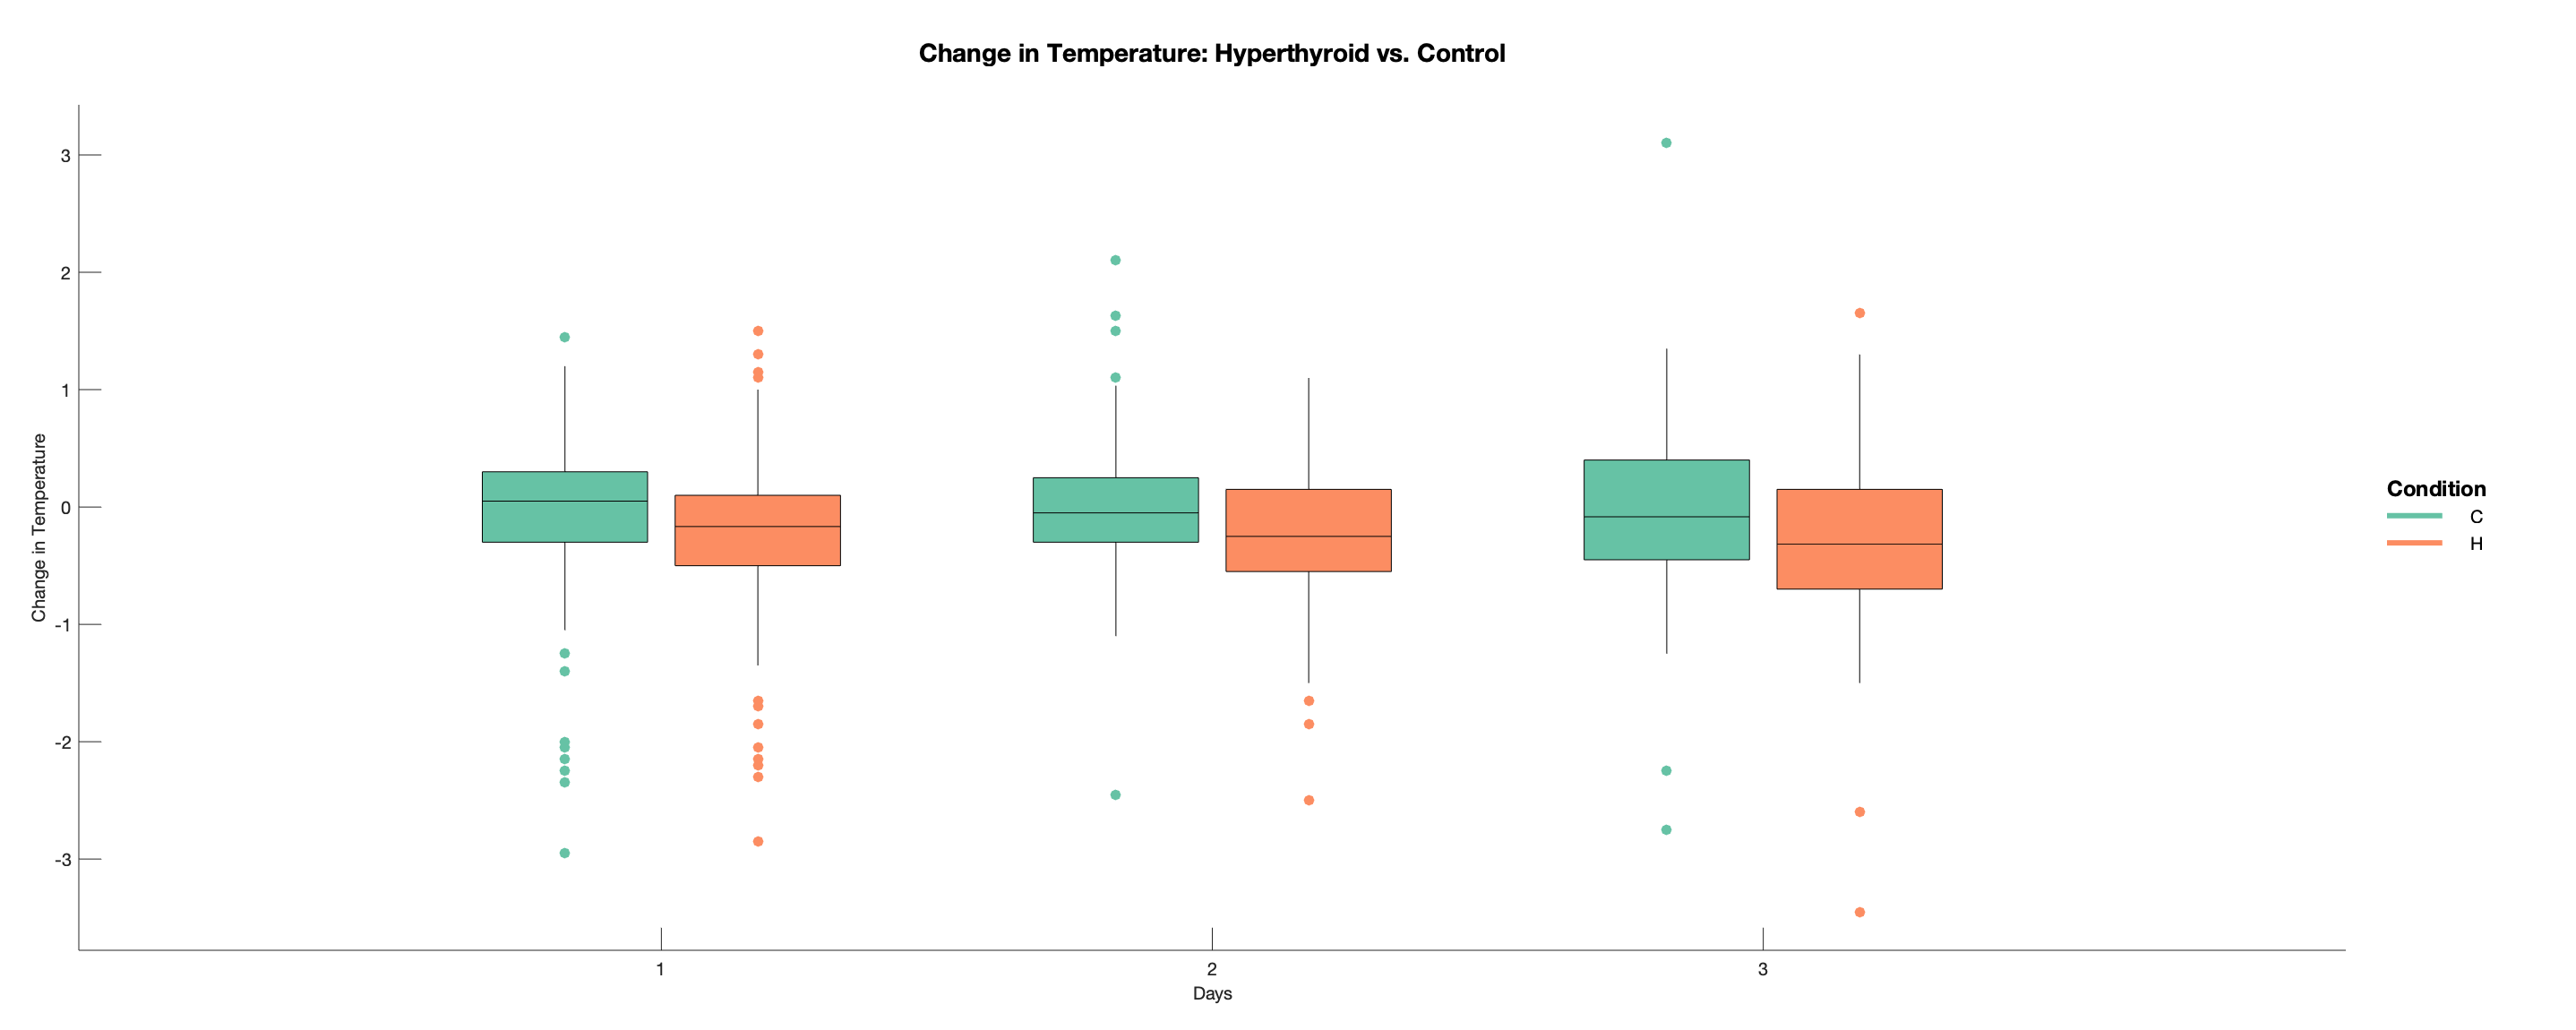

ans =   gramm with properties:

     legend_axe_handle: [1×1 Axes]
      title_axe_handle: [1×1 Axes]
    facet_axes_handles: [1×1 Axes]
               results: [1×1 struct]


a=gramm('x',deltatempstack.Day,'y',deltatempstack.tempchange,'color',deltatempstack.Condition_H_C_,'subset',deltatempstack.Day~="4" & deltatempstack.Day~="5" & deltatempstack.Day~="6"& deltatempstack.Day~="7"& deltatempstack.Day~="8");
a.stat_boxplot();
a.set_names('x','Days','y','Change in Temperature','color','Condition');
a.set_title('Change in Temperature: Hyperthyroid vs. Control');
a.set_color_options('map','brewer2');
figure('Position',[100 100 2000 800]);
a.draw()

## Delta Temp Jittered Scatter Plot

-Days limited to Day 1 through Day 3 of treatment

-Delta temp data 

-Set color scheme to Brewer Dark

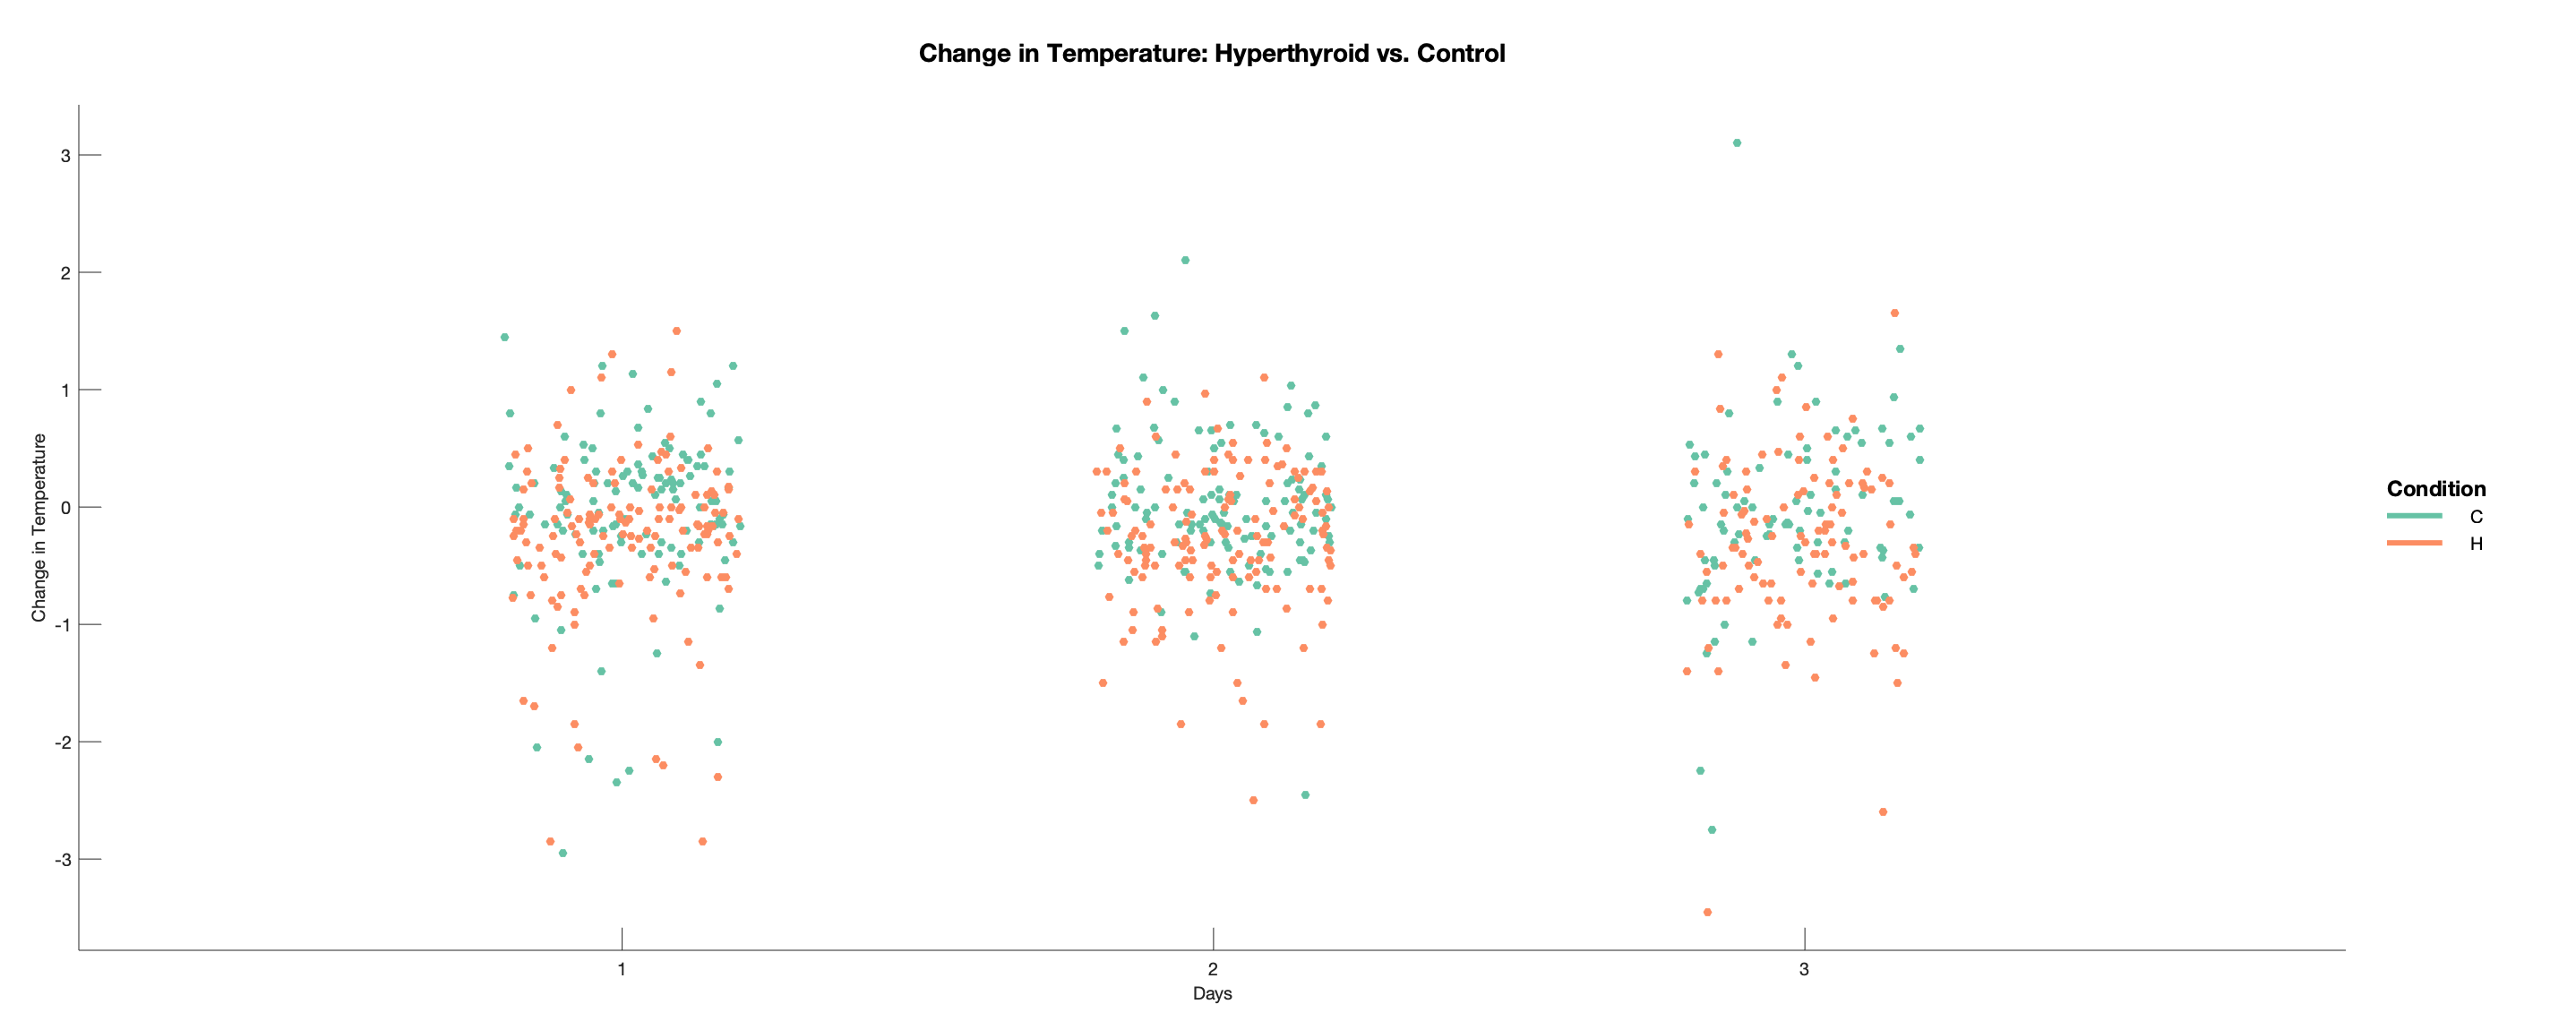

ans =   gramm with properties:

     legend_axe_handle: [1×1 Axes]
      title_axe_handle: [1×1 Axes]
    facet_axes_handles: [1×1 Axes]
               results: [1×1 struct]


a=gramm('x',deltatempstack.Day,'y',deltatempstack.tempchange,'color',deltatempstack.Condition_H_C_,'subset',deltatempstack.Day~="4" & deltatempstack.Day~="5" & deltatempstack.Day~="6"& deltatempstack.Day~="7"& deltatempstack.Day~="8");
a.geom_jitter('width',0.4,'height',0);
a.set_names('x','Days','y','Change in Temperature','color','Condition');
a.set_title('Change in Temperature: Hyperthyroid vs. Control');
a.set_color_options('map','brewer2');
figure('Position',[100 100 2000 800]);
a.draw()

## Delta Temp Normalized Violin Plot

-Days limited to Day 1 through Day 3 of treatment

-Delta temp data 

-Set color scheme to Brewer Dark

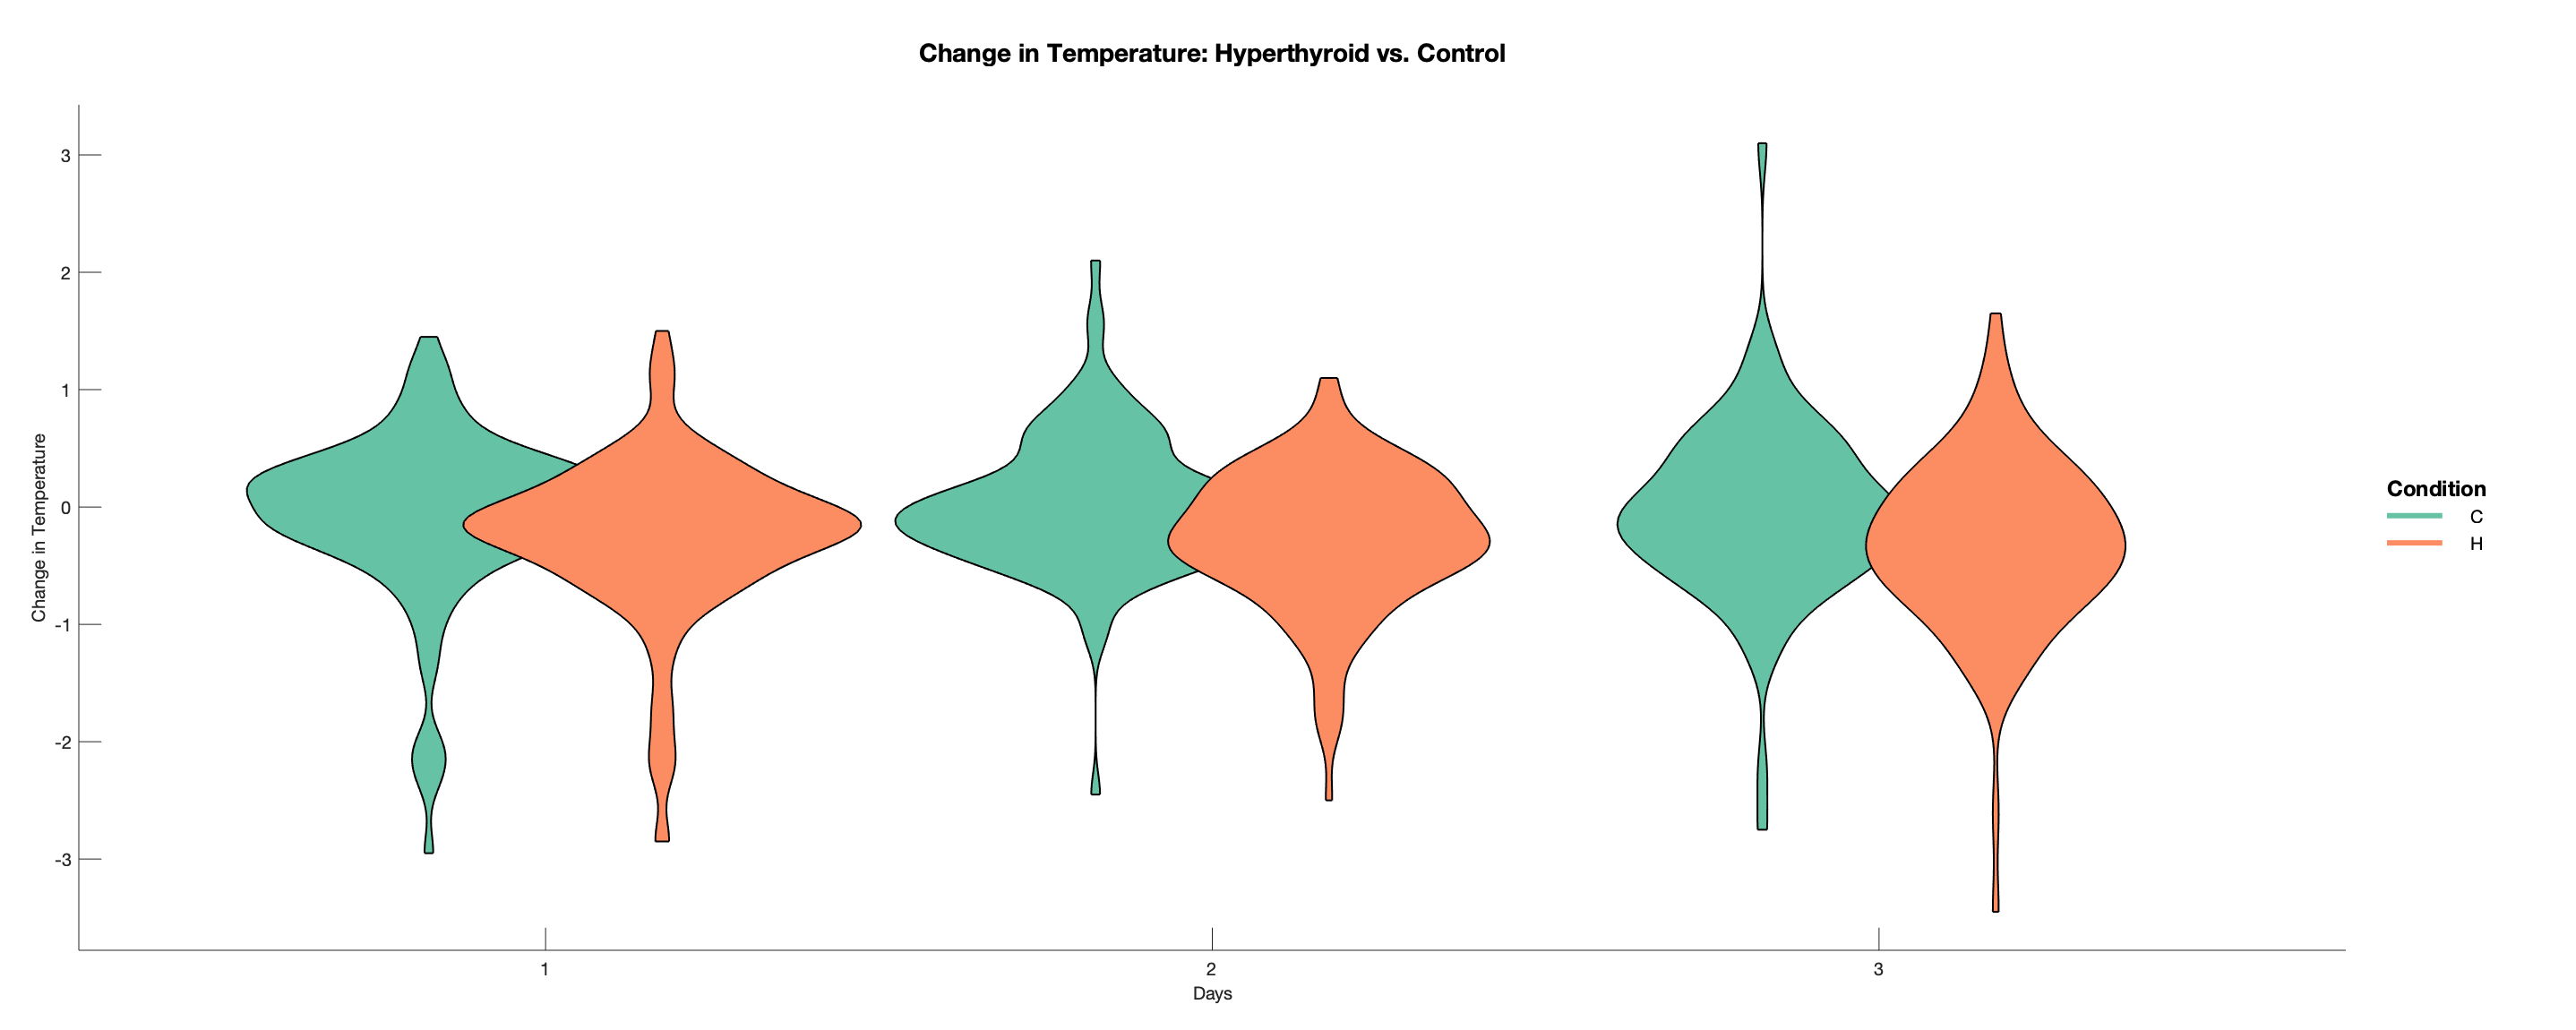

ans =   gramm with properties:

     legend_axe_handle: [1×1 Axes]
      title_axe_handle: [1×1 Axes]
    facet_axes_handles: [1×1 Axes]
               results: [1×1 struct]


a=gramm('x',deltatempstack.Day,'y',deltatempstack.tempchange,'color',deltatempstack.Condition_H_C_,'subset',deltatempstack.Day~="4" & deltatempstack.Day~="5" & deltatempstack.Day~="6"& deltatempstack.Day~="7"& deltatempstack.Day~="8");
a.stat_violin('normalization','area');
a.set_names('x','Days','y','Change in Temperature','color','Condition');
a.set_title('Change in Temperature: Hyperthyroid vs. Control');
a.set_color_options('map','brewer2');
figure('Position',[100 100 2000 800]);
a.draw()

## Delta Temp Violin Plot with Box Plot

-Days limited to Day 1 through Day 3 of treatment

-Delta temp data 

-Set color scheme to Brewer Dark

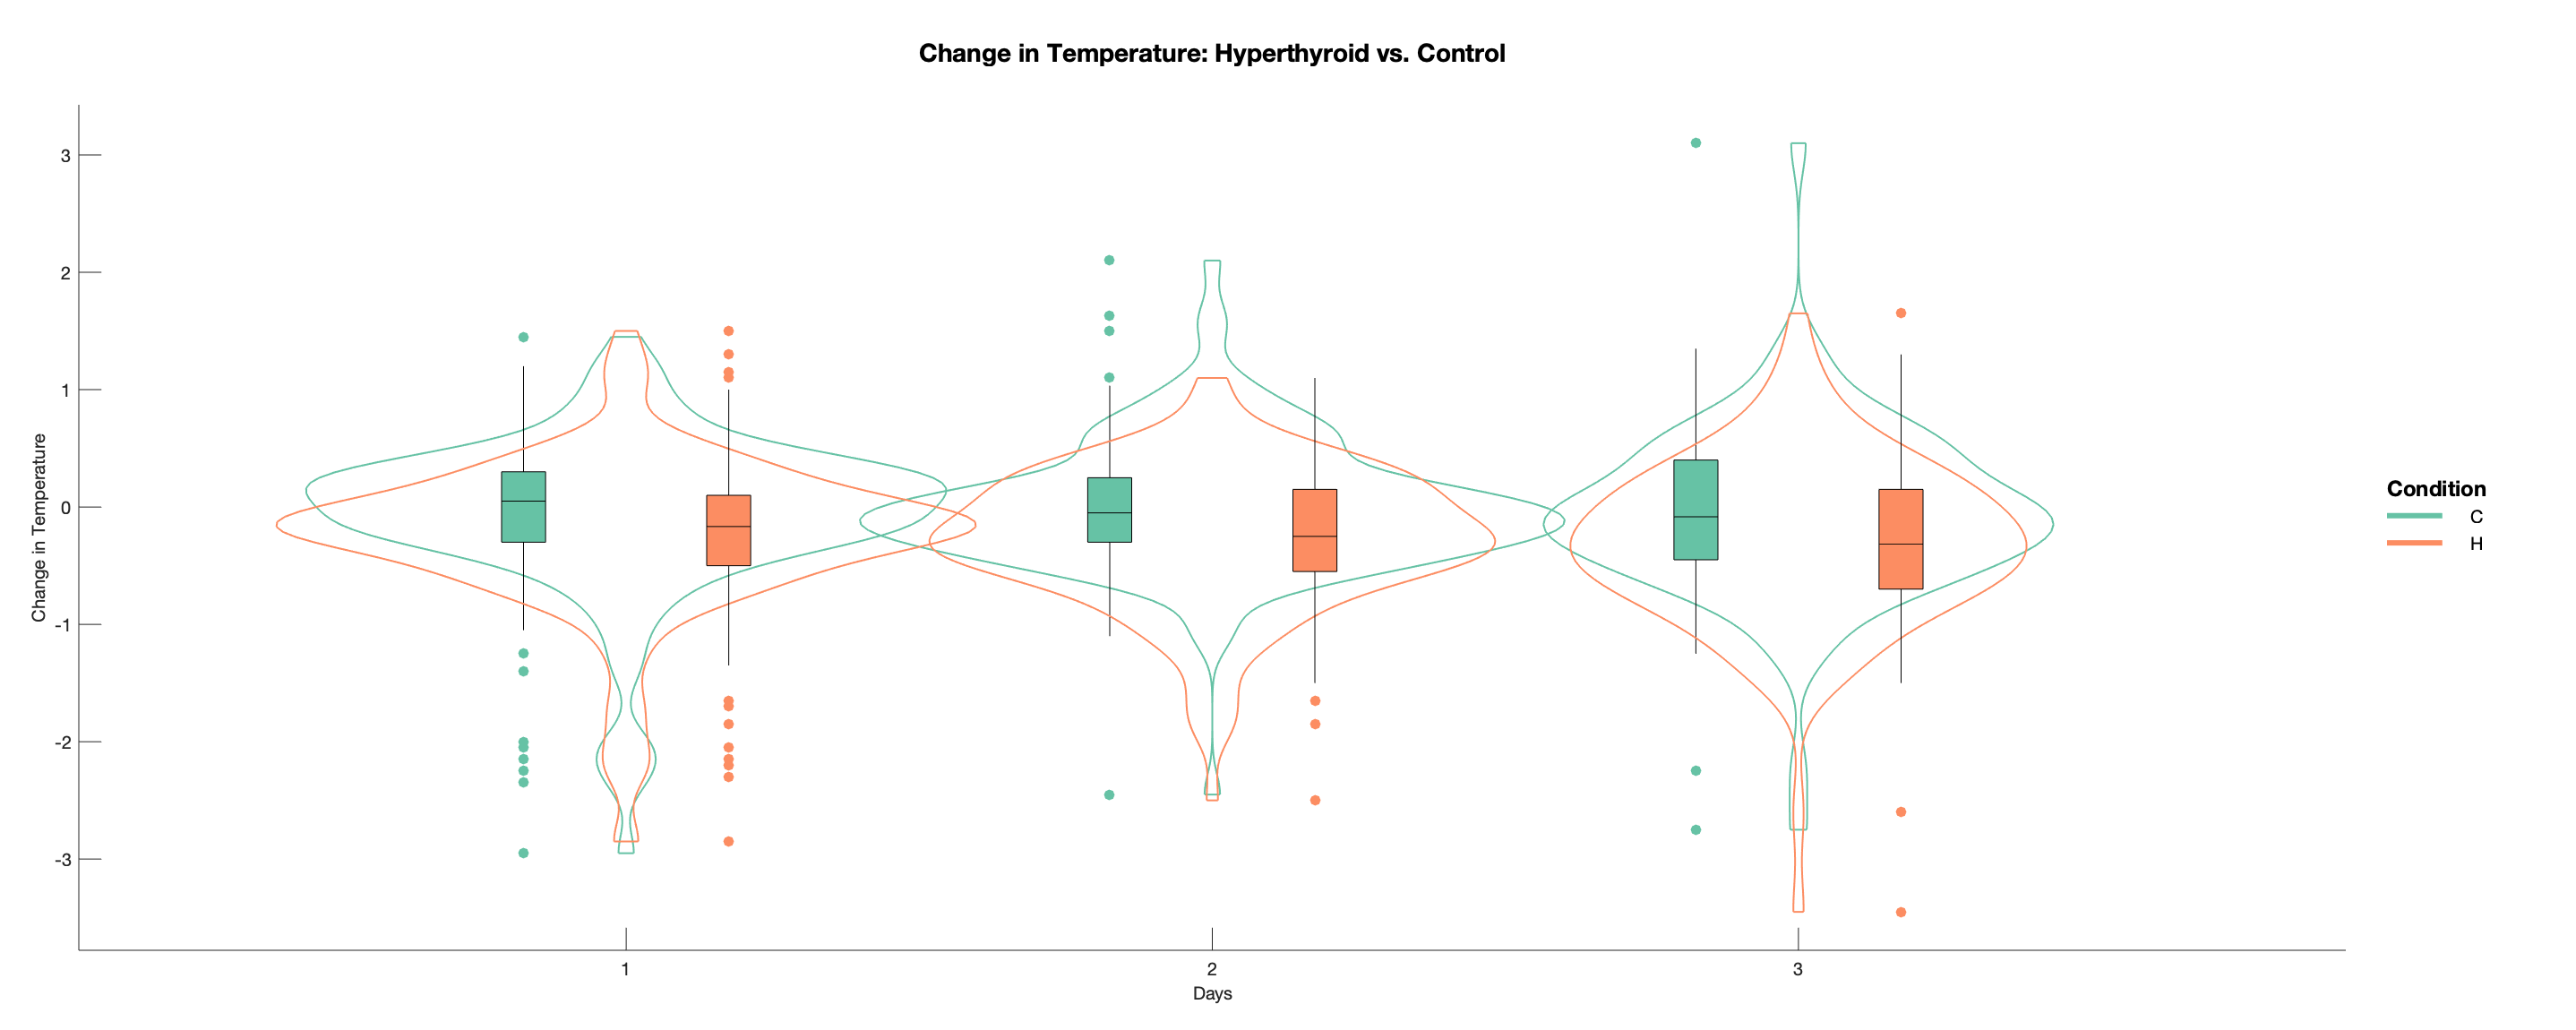

ans =   gramm with properties:

     legend_axe_handle: [1×1 Axes]
      title_axe_handle: [1×1 Axes]
    facet_axes_handles: [1×1 Axes]
               results: [1×1 struct]


a=gramm('x',deltatempstack.Day,'y',deltatempstack.tempchange,'color',deltatempstack.Condition_H_C_,'subset',deltatempstack.Day~="4" & deltatempstack.Day~="5" & deltatempstack.Day~="6"& deltatempstack.Day~="7"& deltatempstack.Day~="8");
a.stat_violin('normalization','area','dodge',0,'fill','edge');
a.stat_boxplot('width',0.15);
a.set_names('x','Days','y','Change in Temperature','color','Condition');
a.set_title('Change in Temperature: Hyperthyroid vs. Control');
a.set_color_options('map','brewer2');
figure('Position',[100 100 2000 800]);
a.draw()